## Analysis and Modeling  of a Boost Converter with Power Processing Reduction for PV Applications


%%% ========================================================================
%  Contents:
%   (I)   Linear small-signal model (Eq. 13) and numerical TFs (ss2tf)
%   (II)  Symbolic poles/zeros:
%           - Transmission zeros via Rosenbrock system matrix
%           - Poles via det(sI-A)=0
%           - TF cross-check via Faddeev–Leverrier (adjugate polynomial)
%   (III) Operating point from averaged steady-state equations (Eqs. 1–3)
%   (IV)  Pole/zero migration sweeps (Fig. 4) in a single 1×4 layout
%   (V)   k-factor and normalized processed power (Fig. 8) in a single 1×3 layout
%   (V1)  Bode transfer function Gvd (Fig.10)
%
%  Modeling conventions (kept consistent throughout the script):
%    States:  x = [ iL ; vC1 ; vC2 ]
%    Inputs:  u1 associated with B1, u2 associated with B2
%    Outputs: C_iL  -> iL,  C_vC1 -> vC1,  C_vC2 -> vC2
%
%  Notes:
%   - Continuous-time analysis (s-plane). Do NOT use zplane().
%   - Requires Control System Toolbox for ss2tf / tf / bode.
%  ========================================================================

clearvars; close all; clc;

%% ========================================================================
%  (I) Symbolic model (Eq. 13)
% ========================================================================

% --- Symbolic variables (real-valued)
syms L D C1 C2 R iE s zo real
n  = 3;
I3 = eye(n);

% --- Linearized state-space model (Eq. 13)
% States: x = [ iL ; vC1 ; vC2 ]
A = [   0        -1/L         D/L ;
      1/C1        0            0  ;
     -D/C2        0       -1/(R*C2) ];

B1 = [ 0 ; -1/C1 ;  1/C2 ];

% B2 includes operating-point dependence (iE) as in Eq. 13
B2 = [ (1-D)*R*iE/L ; 0 ; -iE/C2 ];

% --- Output selection vectors (consistent naming)
C_iL  = [1 0 0];
C_vC1 = [0 1 0];
C_vC2 = [0 0 1];

% --- Direct feedthrough terms (explicit bookkeeping)
D11 = 0; D12 = 0; D21 = 0; D22 = 0;

% --- Symbolic resolvent (sI - A)^(-1) for direct TF reference
Phi_s    = (s*I3 - A);
Phi_sInv = simplify(inv(Phi_s));

%% ========================================================================
%  (I-a) Nominal parameters (TABLE I in the manuscript)
% ========================================================================

D_nom  = 0.5;
C1_nom = 2e-6;
C2_nom = 10e-6;
L_nom  = 110e-6;
R_nom  = 15.36;
iE_nom = 6.25;

params = [ L,    D,    C1,    C2,    R,    iE ];
values = [ L_nom, D_nom, C1_nom, C2_nom, R_nom, iE_nom ];

%% ========================================================================
%  (I-b) Numerical state-space and numerical transfer functions (ss2tf)
% ========================================================================

A_num  = double(subs(A,  params, values));
B1_num = double(subs(B1, params, values));
B2_num = double(subs(B2, params, values));

% Reported TF(s): u2 -> vC2 and u1 -> vC2
C_out = C_vC2;

[numG22, denG22] = ss2tf(A_num, B2_num, C_out, D22);   % u2 -> vC2
[numG21, denG21] = ss2tf(A_num, B1_num, C_out, D21);   % u1 -> vC2

G22 = tf(numG22, denG22);
G21 = tf(numG21, denG21);

disp('==================== Numerical Transfer Functions (Nominal) ====================');

==================== Numerical Transfer Functions (Nominal) ====================


disp('G22 (u2 -> vC2):');  G22

G22 (u2 -> vC2):

G22 =
 
   -625000 s^2 - 2.182e10 s - 2.841e15
  --------------------------------------
  s^3 + 6510 s^2 + 4.773e09 s + 2.959e13
 
Continuous-time transfer function.


disp('G21 (u1 -> vC2):');  G21

G21 (u1 -> vC2):

G21 =
 
   100000 s^2 + 2.562e-07 s + 2.273e14
  --------------------------------------
  s^3 + 6510 s^2 + 4.773e09 s + 2.959e13
 
Continuous-time transfer function.


disp('===============================================================================');


%% ========================================================================
%  (II) Symbolic poles/zeros (Rosenbrock + Leverrier cross-check)
% ========================================================================

% --- (II-a) Transmission zeros via Rosenbrock system matrix determinant:
% Zeros satisfy det([A-zo*I, B; C, 0]) = 0
A_zo = A - zo*I3;

% u2 -> vC2 (used later for the sweep)
M_vC2_u2 = [A_zo, B2;  C_vC2, 0];
z_vC2_u2 = solve(simplify(det(M_vC2_u2)), zo, 'MaxDegree', 2);


% Additional channels (computed for completeness)
M_iL_u2  = [A_zo, B2;  C_iL,  0];
M_vC1_u2 = [A_zo, B2;  C_vC1, 0];
z_iL_u2  = solve(simplify(det(M_iL_u2)),  zo, 'MaxDegree', 2);

z_vC1_u2 = solve(simplify(det(M_vC1_u2)), zo, 'MaxDegree', 2);


M_vC2_u1 = [A_zo, B1;  C_vC2, 0];
z_vC2_u1 = solve(simplify(det(M_vC2_u1)), zo, 'MaxDegree', 2);


% --- (II-b) Poles from characteristic polynomial det(sI - A)=0
charPoly_s = simplify(det(s*I3 - A));
poles_sym  = solve(charPoly_s, s, 'MaxDegree', 3);


% --- (II-c) Faddeev–Leverrier (adjugate polynomial) TF cross-check
P = sym(zeros(n,n,n));
aCoeff = sym(zeros(1,n));        % coefficients a1..an

P(:,:,1)  = eye(n);
aCoeff(1) = -trace(A);

for k = 2:n
    aCoeff(k-1) = -(1/(k-1))*trace(P(:,:,k-1)*A);
    P(:,:,k)    = P(:,:,k-1)*A + aCoeff(k-1)*eye(n);
end
aCoeff(n) = -(1/n)*trace(P(:,:,n)*A);

Adj_sI_A = sym(zeros(n,n));
for i = 1:n
    Adj_sI_A = Adj_sI_A + P(:,:,i)*s^(n-i);
end
Adj_sI_A = simplify(Adj_sI_A);

den_s = s^n;
for i = 1:n
    den_s = den_s + aCoeff(i)*s^(n-i);
end
den_s = simplify(den_s);

% Symbolic TFs of interest
Gvd_leverrier = simplifyFraction( simplify(C_vC2 * Adj_sI_A * B2) / den_s ); % u2 -> vC2
Gvd_direct    = simplifyFraction( C_vC2 * Phi_sInv * B2 );                  % u2 -> vC2

% Poles/zeros extracted from direct TF
[nGvd, dGvd] = numden(Gvd_direct);
poles_Gvd_TF = solve(dGvd, s, 'MaxDegree', 3);

zeros_Gvd_TF = solve(nGvd, s, 'MaxDegree', 2);


disp('==================== Symbolic Results ====================');

==================== Symbolic Results ====================


disp('Zeros (Rosenbrock) for u2 -> vC2:'); disp(z_vC2_u2);

Zeros (Rosenbrock) for u2 -> vC2:


$$\begin{array}{l} \left(\begin{array}{c} -\frac{\sigma_{1}+C_{1}\,\text{D}\,R-C_{1}\,{\text{D}}^{2}\,R}{2\,C_{1}\,L}\\ \frac{\sigma_{1}-C_{1}\,\text{D}\,R+C_{1}\,{\text{D}}^{2}\,R}{2\,C_{1}\,L} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-C_{1}\,\left(-C_{1}\,{\text{D}}^{4}\,R^{2}+2\,C_{1}\,{\text{D}}^{3}\,R^{2}-C_{1}\,{\text{D}}^{2}\,R^{2}+4\,L\right)} \end{array}$$

disp('Poles from det(sI-A)=0:');          disp(poles_sym);

Poles from det(sI-A)=0:


$$\begin{array}{l} \left(\begin{array}{c} \sigma_{1}+\frac{\sigma_{2}}{\sigma_{1}}-\frac{1}{3\,C_{2}\,R}\\ -\frac{\sigma_{1}}{2}-\frac{\sigma_{2}}{2\,\sigma_{1}}-\frac{1}{3\,C_{2}\,R}-\frac{\sqrt{3}\,\left(\sigma_{1}-\frac{\sigma_{2}}{\sigma_{1}}\right)\,\mathrm{i}}{2}\\ -\frac{\sigma_{1}}{2}-\frac{\sigma_{2}}{2\,\sigma_{1}}-\frac{1}{3\,C_{2}\,R}+\frac{\sqrt{3}\,\left(\sigma_{1}-\frac{\sigma_{2}}{\sigma_{1}}\right)\,\mathrm{i}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\sqrt{{\left(\frac{1}{27\,{C_{2}}^{3}\,R^{3}}+\frac{1}{2\,C_{1}\,C_{2}\,L\,R}-\sigma_{3}\right)}^{2}-{\sigma_{2}}^{3}}-\frac{1}{27\,{C_{2}}^{3}\,R^{3}}-\frac{1}{2\,C_{1}\,C_{2}\,L\,R}+\sigma_{3}\right)}^{1/3}\\ \sigma_{2}=\frac{1}{9\,{C_{2}}^{2}\,R^{2}}-\frac{C_{1}\,R\,{\text{D}}^{2}+C_{2}\,R}{3\,C_{1}\,C_{2}\,L\,R}\\ \sigma_{3}=\frac{C_{1}\,R\,{\text{D}}^{2}+C_{2}\,R}{6\,C_{1}\,{C_{2}}^{2}\,L\,R^{2}} \end{array}$$

disp('Gvd via Leverrier Eq. (14):'); disp(Gvd_leverrier);

Gvd via Leverrier (cross-check):


$$-\frac{R\,\mathrm{iE}\,\left(-C_{1}\,R\,{\text{D}}^{2}\,s+C_{1}\,R\,\text{D}\,s+C_{1}\,L\,s^{2}+1\right)}{C_{1}\,R\,{\text{D}}^{2}\,s+C_{1}\,C_{2}\,L\,R\,s^{3}+C_{1}\,L\,s^{2}+C_{2}\,R\,s+1}$$

disp('Gvd via direct inversion:');        disp(Gvd_direct);

Gvd via direct inversion:


$$-\frac{-C_{1}\,\mathrm{iE}\,{\text{D}}^{2}\,R^{2}\,s+C_{1}\,\mathrm{iE}\,\text{D}\,R^{2}\,s+C_{1}\,L\,\mathrm{iE}\,R\,s^{2}+\mathrm{iE}\,R}{C_{1}\,R\,{\text{D}}^{2}\,s+C_{1}\,C_{2}\,L\,R\,s^{3}+C_{1}\,L\,s^{2}+C_{2}\,R\,s+1}$$

disp('Poles from TF denominator (Gvd):'); disp(poles_Gvd_TF);

Poles from TF denominator (Gvd):


$$\begin{array}{l} \left(\begin{array}{c} \sigma_{1}+\frac{\sigma_{2}}{\sigma_{1}}-\frac{1}{3\,C_{2}\,R}\\ -\frac{\sigma_{1}}{2}-\frac{\sigma_{2}}{2\,\sigma_{1}}-\frac{1}{3\,C_{2}\,R}-\frac{\sqrt{3}\,\left(\sigma_{1}-\frac{\sigma_{2}}{\sigma_{1}}\right)\,\mathrm{i}}{2}\\ -\frac{\sigma_{1}}{2}-\frac{\sigma_{2}}{2\,\sigma_{1}}-\frac{1}{3\,C_{2}\,R}+\frac{\sqrt{3}\,\left(\sigma_{1}-\frac{\sigma_{2}}{\sigma_{1}}\right)\,\mathrm{i}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\sqrt{{\left(\frac{1}{27\,{C_{2}}^{3}\,R^{3}}+\frac{1}{2\,C_{1}\,C_{2}\,L\,R}-\sigma_{3}\right)}^{2}-{\sigma_{2}}^{3}}-\frac{1}{27\,{C_{2}}^{3}\,R^{3}}-\frac{1}{2\,C_{1}\,C_{2}\,L\,R}+\sigma_{3}\right)}^{1/3}\\ \sigma_{2}=\frac{1}{9\,{C_{2}}^{2}\,R^{2}}-\frac{C_{1}\,R\,{\text{D}}^{2}+C_{2}\,R}{3\,C_{1}\,C_{2}\,L\,R}\\ \sigma_{3}=\frac{C_{1}\,R\,{\text{D}}^{2}+C_{2}\,R}{6\,C_{1}\,{C_{2}}^{2}\,L\,R^{2}} \end{array}$$

disp('Zeros from TF numerator   (Gvd):'); disp(zeros_Gvd_TF);

Zeros from TF numerator   (Gvd):


$$\begin{array}{l} \left(\begin{array}{c} -\frac{\sigma_{1}+C_{1}\,\text{D}\,R-C_{1}\,{\text{D}}^{2}\,R}{2\,C_{1}\,L}\\ \frac{\sigma_{1}-C_{1}\,\text{D}\,R+C_{1}\,{\text{D}}^{2}\,R}{2\,C_{1}\,L} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-C_{1}\,\left(-C_{1}\,{\text{D}}^{4}\,R^{2}+2\,C_{1}\,{\text{D}}^{3}\,R^{2}-C_{1}\,{\text{D}}^{2}\,R^{2}+4\,L\right)} \end{array}$$

disp('==========================================================');


%% ========================================================================
%  (III) Operating point from averaged steady-state equations (Eqs. 1–3)
% ========================================================================

syms vC1_op iL_op vC2_op real

% Equilibrium conditions (derivatives equal to zero)
eq1 = -vC1_op/L + D*vC2_op/L == 0;                    % Eq. (1)
eq2 =  iL_op/C1  - iE/C1       == 0;                  % Eq. (2)
eq3 = -D*iL_op/C2 - vC2_op/(R*C2) + iE/C2 == 0;       % Eq. (3)

solOP = solve([eq1, eq2, eq3], [iL_op, vC1_op, vC2_op]);
iL_star  = simplifyFraction(solOP.iL_op);
vC1_star = simplifyFraction(solOP.vC1_op);
vC2_star = simplifyFraction(solOP.vC2_op);

disp('==================== Operating Point (Eqs. 1–3) ====================');

==================== Operating Point (Eqs. 1–3) ====================


disp('iL*  ='); disp(iL_star);

iL*  =


$$\mathrm{iE}$$

disp('vC1* ='); disp(vC1_star);

vC1* =


$$\text{D}\,R\,\left(\mathrm{iE}-\text{D}\,\mathrm{iE}\right)$$

disp('vC2* ='); disp(vC2_star);

vC2* =


$$R\,\left(\mathrm{iE}-\text{D}\,\mathrm{iE}\right)$$

disp('====================================================================');

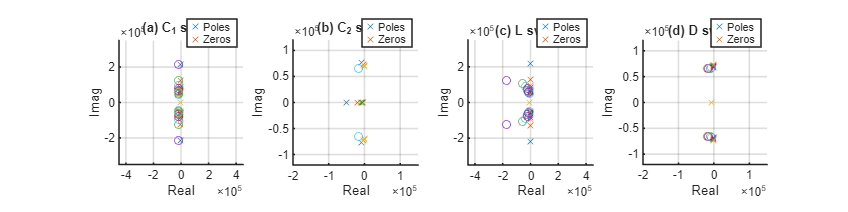


%% ========================================================================
%  (IV) Fig. 4: Pole/zero migration sweep (single figure: 1×4)
% ========================================================================

N = 10;
C1_array = linspace(C1_nom*0.1, C1_nom*1.9, N);
C2_array = linspace(C2_nom*0.1, C2_nom*1.9, N);
L_array  = linspace(L_nom*0.1,  L_nom*1.9,  N);
D_array  = linspace(0.1, 0.9, N);

% Symbolic expressions used for substitution
Z_sym = z_vC2_u2;      % zeros of u2 -> vC2
P_sym = poles_sym;     % poles from det(sI-A)=0

% Preallocate (2 zeros, 3 poles)
Z_C1 = zeros(2,N); P_C1 = zeros(3,N);
Z_C2 = zeros(2,N); P_C2 = zeros(3,N);
Z_L  = zeros(2,N); P_L  = zeros(3,N);
Z_D  = zeros(2,N); P_D  = zeros(3,N);

for i = 1:N
    values_C1 = [L_nom, D_nom, C1_array(i), C2_nom, R_nom, iE_nom];
    Z_C1(:,i) = double(subs(Z_sym, params, values_C1));
    P_C1(:,i) = double(subs(P_sym, params, values_C1));

    values_C2 = [L_nom, D_nom, C1_nom, C2_array(i), R_nom, iE_nom];
    Z_C2(:,i) = double(subs(Z_sym, params, values_C2));
    P_C2(:,i) = double(subs(P_sym, params, values_C2));

    values_L  = [L_array(i), D_nom, C1_nom, C2_nom, R_nom, iE_nom];
    Z_L(:,i)  = double(subs(Z_sym, params, values_L));
    P_L(:,i)  = double(subs(P_sym, params, values_L));

    values_D  = [L_nom, D_array(i), C1_nom, C2_nom, R_nom, iE_nom];
    Z_D(:,i)  = double(subs(Z_sym, params, values_D));
    P_D(:,i)  = double(subs(P_sym, params, values_D));
end

% Axis limits (as used in your manuscript)
xlim_CL = [-4.5e5  4.5e5];  ylim_CL = [-3.5e5  3.5e5];
xlim_CD = [-2.0e5  1.5e5];  ylim_CD = [-1.2e5  1.2e5];

fig4 = figure('Name','Fig. 4 - Pole/Zero Migration','Color','w'); clf(fig4);
set(fig4,'Position',[100 100 1400 350]);

ax41 = subplot(1,4,1); hold on; grid on;
plot(real(P_C1), imag(P_C1), 'x'); plot(real(Z_C1), imag(Z_C1), 'o');
title('(a) C_1 sweep'); xlabel('Real'); ylabel('Imag');
legend('Poles','Zeros','Location','best');
xlim(xlim_CL); ylim(ylim_CL); pbaspect([1 1 1]);

ax42 = subplot(1,4,2); hold on; grid on;
plot(real(P_C2), imag(P_C2), 'x'); plot(real(Z_C2), imag(Z_C2), 'o');
title('(b) C_2 sweep'); xlabel('Real'); ylabel('Imag');
legend('Poles','Zeros','Location','best');
xlim(xlim_CD); ylim(ylim_CD); pbaspect([1 1 1]);

ax43 = subplot(1,4,3); hold on; grid on;
plot(real(P_L),  imag(P_L),  'x'); plot(real(Z_L),  imag(Z_L),  'o');
title('(c) L sweep'); xlabel('Real'); ylabel('Imag');
legend('Poles','Zeros','Location','best');
xlim(xlim_CL); ylim(ylim_CL); pbaspect([1 1 1]);

ax44 = subplot(1,4,4); hold on; grid on;
plot(real(P_D),  imag(P_D),  'x'); plot(real(Z_D),  imag(Z_D),  'o');
title('(d) D sweep'); xlabel('Real'); ylabel('Imag');
legend('Poles','Zeros','Location','best');
xlim(xlim_CD); ylim(ylim_CD); pbaspect([1 1 1]);

axFig4 = [ax41 ax42 ax43 ax44];
for k = 1:length(axFig4)
    axFig4(k).GridLineWidth = 1.2;
    axFig4(k).LineWidth     = 1.2;
    axFig4(k).FontSize      = 9;
end

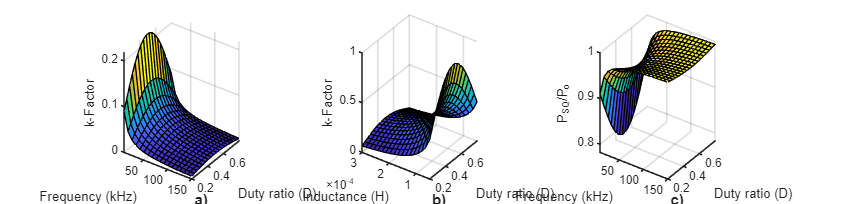




%% ========================================================================
%  (V) Fig. 8: k-factor and normalized processed power (single figure: 1×3)
% ========================================================================

% Sweep definitions (paper-style, moderate sampling)
ND  = 18;
Nfs = 18;
NL  = 18;
fs0=5000;
fs_vec   = linspace(10e3, 150e3, Nfs);        % 10–150 kHz
D_vec_a  = linspace(0.8, 0.2, ND);            % panel (a)
D_vec_bc = linspace(0.2, 0.8, ND);            % panels (b,c)
L_vec_b  = linspace(300e-6, 50e-6, NL);       % 300 uH -> 50 uH (descending)

% (a) kappa vs (fs, D)
[FS_a, D1] = meshgrid(fs_vec, D_vec_a);
kappa_a = (D1.^2 .* (1 - D1).^2 .* R_nom) ./ (4 .* L_nom .* FS_a);

% (b) kappa vs (L, D) with fs fixed at fs0
[Lm, D2] = meshgrid(L_vec_b, D_vec_bc);
kappa_b  = (D2.^2 .* (1 - D2).^2 .* R_nom) ./ (4 .* Lm .* fs0);

% (c) normalized processed power: P_SQ/P_o = 1 - kappa(D,fs)
[FS_c, D3] = meshgrid(fs_vec, D_vec_bc);
kappa_c     = (D3.^2 .* (1 - D3).^2 .* R_nom) ./ (4 .* L_nom .* FS_c);
PSQ_over_Po = 1 - kappa_c;
PSQ_over_Po = max(min(PSQ_over_Po, 1), 0);    % optional clipping

fig8 = figure('Name','Fig. 8','Color','w'); clf(fig8);
set(fig8,'Position',[100 100 1500 360]);

az = 35; el = 25;

% Panel (a)
ax81 = subplot(1,3,1);
surf(ax81, FS_a/1e3, D1, kappa_a, 'EdgeColor','k');
grid(ax81,'on');
xlabel(ax81,'Frequency (kHz)'); ylabel(ax81,'Duty ratio (D)'); zlabel(ax81,'k-Factor');
view(ax81, az, el);
ax81.XLim = [10 150]; ax81.YLim = [0.2 0.8];
ax81.GridLineWidth = 1.2; ax81.LineWidth = 1.2; ax81.FontSize = 9;

% Panel (b)
ax82 = subplot(1,3,2);
surf(ax82, Lm, D2, kappa_b, 'EdgeColor','k');
grid(ax82,'on');
xlabel(ax82,'Inductance (H)'); ylabel(ax82,'Duty ratio (D)'); zlabel(ax82,'k-Factor');
view(ax82, az, el);
ax82.XLim = [50e-6 300e-6]; ax82.XDir = 'reverse'; ax82.YLim = [0.2 0.8];
ax82.XAxis.Exponent = -4;
ax82.GridLineWidth = 1.2; ax82.LineWidth = 1.2; ax82.FontSize = 9;

% Panel (c)
ax83 = subplot(1,3,3);
surf(ax83, FS_c/1e3, D3, PSQ_over_Po, 'EdgeColor','k');
grid(ax83,'on');
xlabel(ax83,'Frequency (kHz)'); ylabel(ax83,'Duty ratio (D)'); zlabel(ax83,'P_{SQ}/P_o');
view(ax83, az, el);
ax83.XLim = [10 150]; ax83.YLim = [0.2 0.8];
ax83.GridLineWidth = 1.2; ax83.LineWidth = 1.2; ax83.FontSize = 9;

% --- Panel labels BELOW axes (no functions; robust for PDF export)
u1 = ax81.Units; ax81.Units = 'normalized'; p1 = ax81.Position; ax81.Units = u1;
u2 = ax82.Units; ax82.Units = 'normalized'; p2 = ax82.Position; ax82.Units = u2;
u3 = ax83.Units; ax83.Units = 'normalized'; p3 = ax83.Position; ax83.Units = u3;
yoff = 0.08;

annotation('textbox',[p1(1)+p1(3)/2-0.03, p1(2)-yoff, 0.06, 0.05], ...
    'String','a)', 'EdgeColor','none', 'HorizontalAlignment','center', ...
    'VerticalAlignment','top', 'FontWeight','bold', 'FontSize',11);

annotation('textbox',[p2(1)+p2(3)/2-0.03, p2(2)-yoff, 0.06, 0.05], ...
    'String','b)', 'EdgeColor','none', 'HorizontalAlignment','center', ...
    'VerticalAlignment','top', 'FontWeight','bold', 'FontSize',11);

annotation('textbox',[p3(1)+p3(3)/2-0.03, p3(2)-yoff, 0.06, 0.05], ...
    'String','c)', 'EdgeColor','none', 'HorizontalAlignment','center', ...
    'VerticalAlignment','top', 'FontWeight','bold', 'FontSize',11);



% Quick numeric sanity output
fprintf('Fig. 8(a): kappa max = %.4f\n', max(kappa_a(:)));

Fig. 8(a): kappa max = 0.2176


fprintf('Fig. 8(c): PSQ/Po min = %.4f, max = %.4f\n', min(PSQ_over_Po(:)), max(PSQ_over_Po(:)));

Fig. 8(c): PSQ/Po min = 0.7824, max = 0.9940




%% ========================================================================
%  Fig. 10: Frequency response of G22 (Gvd) at nominal parameters
%  Note: G22 is the numerical TF obtained with ss2tf (u2 -> vC2)
% ========================================================================

disp('==================== Fig. 10 ====================');

==================== Fig. 10 ====================


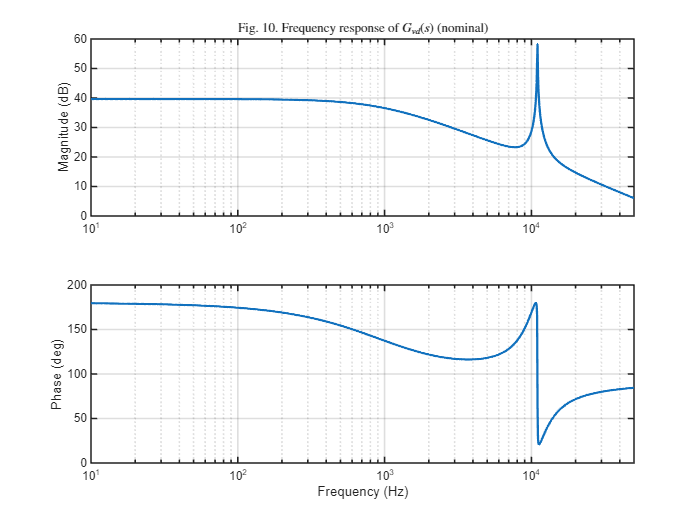


% Frequency range (Hz) - adjust if needed to match the manuscript
f1 = 10;          % start frequency [Hz]
f2 = 50000;       % end frequency   [Hz]
Nf = 1200;        % number of points (smooth curve)

f = logspace(log10(f1), log10(f2), Nf).';   % Hz
w = 2*pi*f;                                   % rad/s

% Evaluate bode data (magnitude and phase)
[mag_lin, ph_deg] = bode(G22, w);
mag_lin = squeeze(mag_lin);
ph_deg  = squeeze(ph_deg);

mag_dB = 20*log10(mag_lin);

% Plot (paper-style)
fig10 = figure('Name','Fig. 10 - Frequency Response of G_{vd}','Color','w'); clf(fig10);
set(fig10,'Position',[100 100 700 520]);

% ---- Magnitude
subplot(2,1,1);
semilogx(f, mag_dB, 'LineWidth', 1.7); grid on;
ylabel('Magnitude (dB)');
title('Fig. 10. Frequency response of $G_{vd}(s)$ (nominal)','Interpreter','latex');
xlim([f1 f2]);

% ---- Phase
subplot(2,1,2);
semilogx(f, ph_deg, 'LineWidth', 1.7); grid on;
ylabel('Phase (deg)');
xlabel('Frequency (Hz)');
xlim([f1 f2]);

% Optional: make axes/grid thicker for journal-style rendering
ax = findall(fig10,'Type','axes');
for k = 1:length(ax)
    ax(k).GridLineWidth = 1.2;
    ax(k).LineWidth     = 1.2;
    ax(k).FontSize      = 9;
end




disp('==================== Script finished successfully ====================');

==================== Script finished successfully ====================
